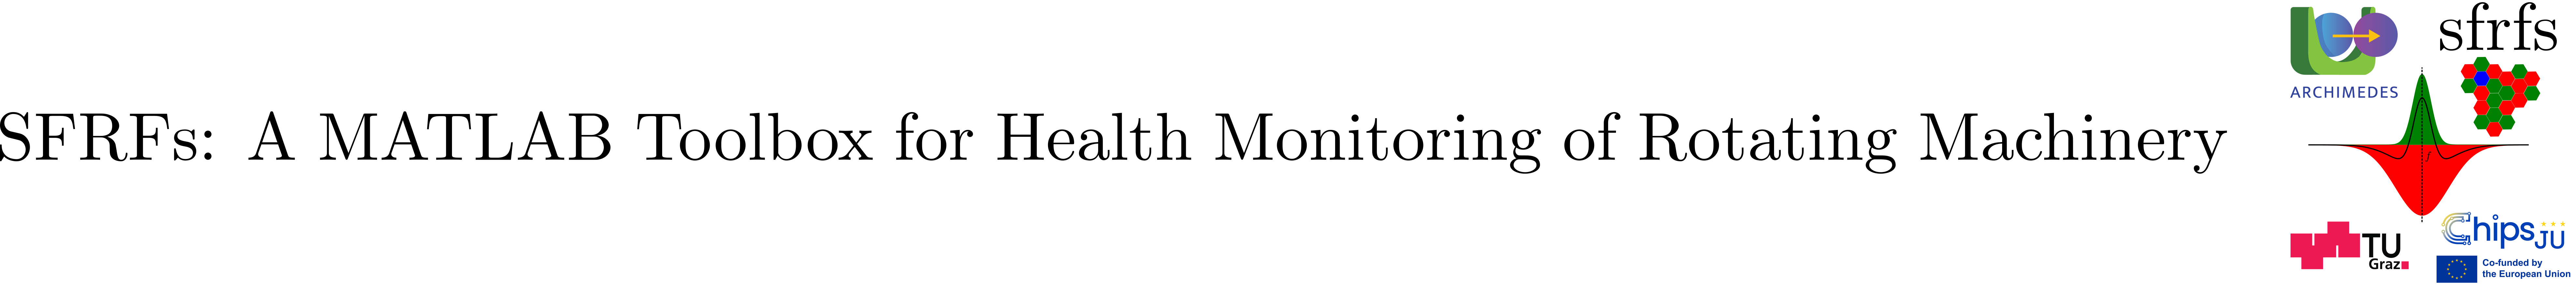

# RunToFailureRFGFsFilteredSpectraViewer

## Summary

`RunToFailureRFGFsFilteredSpectraViewer` is an embeddable visualization component for inspecting run-to-failure spectra after filtering by a selected RFGF mask (Center, Surround, or Contrast). It renders the resulting response matrix as a log10 image over frequency and snapshot index. 

## Description

This viewer delegates all computations to `CenterSurroundCompute.compute()`, then visualizes one of the returned response matrices:

- **CENTER**: center-filtered spectral response (`Rc`)

- **SURROUND**: surround-filtered spectral response (`Rs`)

- **CONTRAST**: contrast response (`contrast`)

For contrast images, the viewer supports selecting which signed component to visualize on the log scale through `invertGainSign`. 

### Properties

### Constructor

#### Syntax

- v = viz.RunToFailureRFGFsFilteredSpectraViewer(Name=Value, ...)

#### Parameters (Name=Value)

### Methods

#### `renderFiltered` selection rules

Exactly one selection mechanism must be used:

- **Row selection**: `renderFiltered(row=...)`

- **Semantic selection**: `renderFiltered(faultType=..., selection=...)`

The semantic selection requires an `OperatingConditionSelection`. 

#### `renderFiltered` parameters (Name=Value)

### See also

[RFGFViewer](matlab:open('./RFGFViewer.mlx')), [RunToFailureSFRFsViewer](matlab:open('./RunToFailureSFRFsViewer.mlx')), [CenterSurroundCompute](matlab:open('./CenterSurroundCompute.mlx')), [ReceptiveFieldResponseFunctions](matlab:open('./ReceptiveFieldGainFunctions.mlx')), [ContrastMappings](matlab:open('./ContrastMappings.mlx'))

## Example

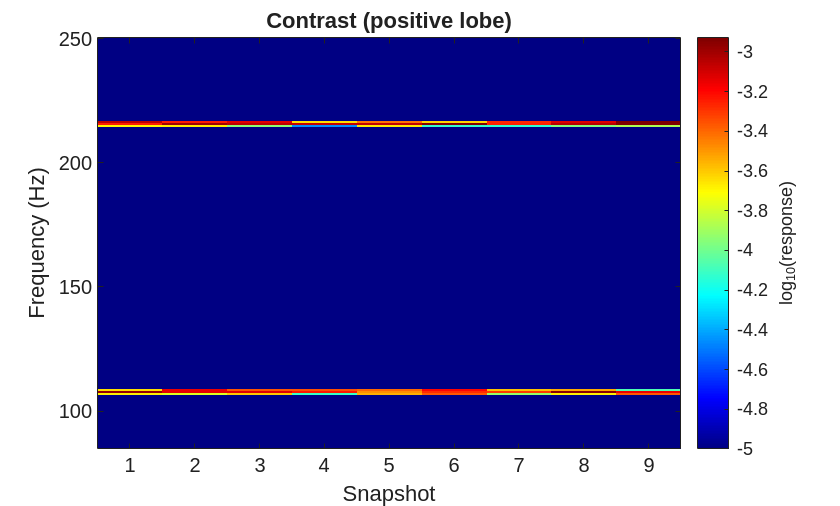

% Example overview
% 1. Define snapshot metadata and operating conditions
% 2. Create mock ensemble (EnsembleMock)
% 3. Create EnsembleBroker
% 4. Execute FFTEnsembleProcessor
% 5. Reconfigure datastore via EnsembleDatastoreRegistry
% 6. Read processed member table
% 7. Render filtered spectra visualizations

% Seed random number generator
rng(0);

% Snapshot descriptor (XJTU-SY values, Wang et al.[2] )
sp = ParametersSnapshot( ...
    samplingFrequency = 25600, ...
    duration = 1.28, ...
    stride = 60);

% Operating conditions (must match mock ensemble)
speeds = [35; 37.5; 40];
loads  = [12; 11; 10];
oc = OperatingConditions(speeds, loads);

% Bearing geometry
bp = ParametersRollingBearings( ...
    numRollingElements = 8, ...
    ballDiameter = 7.92, ...
    pitchDiameter = 34.55, ...
    contactAngle = 0);

% Shared SFRFs parameters
sharedParams = SFRFsParameters.buildSFRFsParameters( ...
    order = 0, ...
    numSidebands = 2, ...
    numHarmonics = 10, ...
    centerMask = GaussianMaskParameters( ...
        bandwidth = 4, ...
        sigmaRule = 1.0253), ...
    surroundMask = GaussianMaskParameters( ...
        bandwidth = 12, ...
        sigmaRule = 0.8905), ...
    inhibitionFactor = 0.8647);

sfrfsParams = SFRFsParametersRollingBearings( ...
    SameForAllFaultTypes = sharedParams);

% Build frequency bands and gain functions
bfb = BearingFrequencyBands( ...
    bearingParams = bp, ...
    sfrfsParams = sfrfsParams, ...
    operatingConditions = oc);
bfb.computeBands();

rfgfs = ReceptiveFieldGainFunctions(bfb);
rfgfs.computeGainFunctions(sp.getFrequencyDomain());

% Mock ensemble with random signals
%% Mock ensemble + broker + FFT processor

temporalCols = { ...
    "HorizontalAcceleration", ...
    "VerticalAcceleration"};

ensembleMock = EnsembleMock( ...
    numMembers = 1, ...
    nSamples = sp.getTotalSamples(), ...
    speeds = speeds, ...
    loads = loads);
ensembleMock.prepare();
clean = onCleanup(@() ensembleMock.cleanup());

broker = EnsembleBroker( ...
    ensembleObject = ensembleMock.fileEnsembleDS, ...
    getFilesFunction = @(obj) obj.Files, ...
    temporalSnapshotColumns = temporalCols);

processor = FFTEnsembleProcessor( ...
    numWorkers = 2, ...
    ensemble = broker);

processor.process();

% Important: reconfigure datastore to expose new FFT columns
FFTCols = string(cellfun( ...
    @(c) broker.mapToSpectralColumn(c), ...
    temporalCols, ...
    UniformOutput = false)).';

% Register ensemble
ensName = "mock-ensemble";
EnsembleDatastoreRegistry.addEnsemble( ...
    name = ensName, ...
    datastore = broker.ensemble);

ensemble = EnsembleDatastoreRegistry.reconfigureEnsemble( ...
    name = ensName, ...
    DataVariables = unique([ ...
        broker.ensemble.DataVariables(:); FFTCols(:)], "stable"), ...
    SelectedVariables = unique([ ...
        broker.ensemble.SelectedVariables(:); FFTCols(:)], "stable"));

reset(ensemble);
member = read(ensemble);

%% Viewer

import structs.FrequencyBankMasksSchema

v = viz.RunToFailureRFGFsFilteredSpectraViewer( ...
    memberTable = member, ...
    snapshotParameters = sp, ...
    rfgfs = rfgfs);

sel = OperatingConditionSelection(speed = 35, load = 12);
ft  = SFRFsParametersRollingBearings.OUTER_RACE_FAULT_TYPE_NAME;

specCol = broker.mapToSpectralColumn("HorizontalAcceleration");

v.renderFiltered( ...
    spectralColumn = specCol, ...
    faultType = ft, ...
    selection = sel, ...
    maskType = FrequencyBankMasksSchema.CONTRAST, ...
    freqRangeHz = [85 250], ...
    titleText = "Contrast (positive lobe)", ...
    invertGainSign = false);

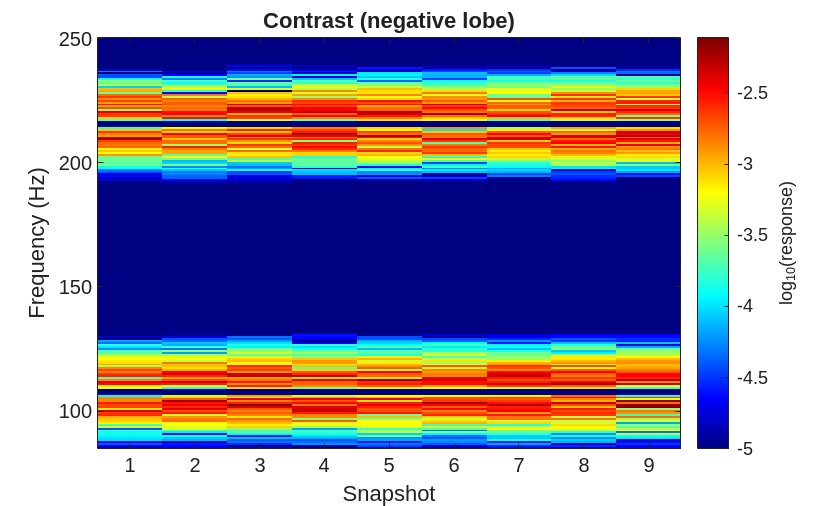


v.renderFiltered( ...
    spectralColumn = specCol, ...
    faultType = ft, ...
    selection = sel, ...
    maskType = FrequencyBankMasksSchema.CONTRAST, ...
    freqRangeHz = [85 250], ...
    titleText = "Contrast (negative lobe)", ...
    invertGainSign = true);

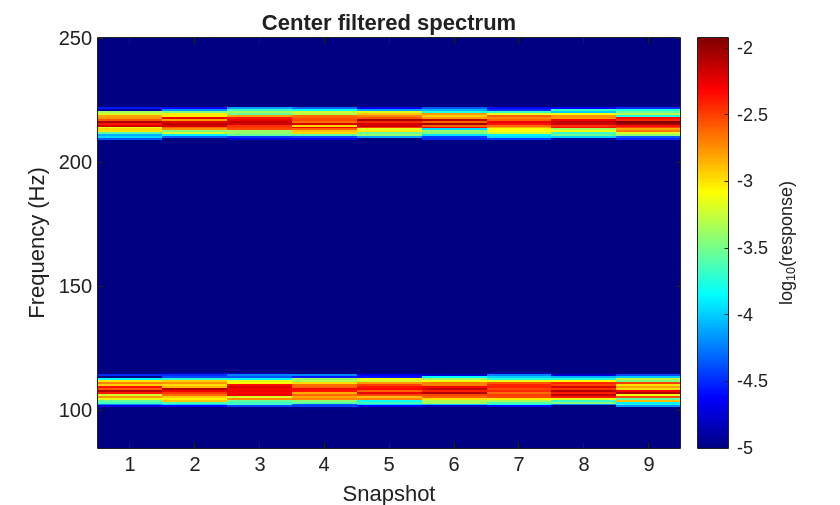


v.renderFiltered( ...
    spectralColumn = specCol, ...
    faultType = ft, ...
    selection = sel, ...
    maskType = FrequencyBankMasksSchema.CENTER, ...
    freqRangeHz = [85 250], ...
    titleText = "Center filtered spectrum");

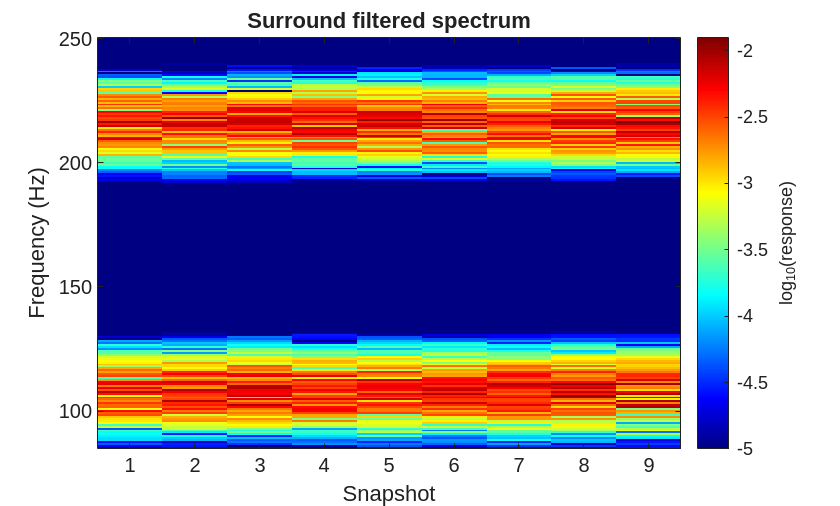


v.renderFiltered( ...
    spectralColumn = specCol, ...
    faultType = ft, ...
    selection = sel, ...
    maskType = FrequencyBankMasksSchema.SURROUND, ...
    freqRangeHz = [85 250], ...
    titleText = "Surround filtered spectrum");

## API documentation

### MATLAB help

help viz.RunToFailureRFGFsFilteredSpectraViewer

 RunToFailureRFGFsFilteredSpectraViewer
 
  Current implementation:
    - All computation is delegated to CenterSurroundCompute.compute().
    - The viewer renders response matrices as log10 images.
 
  Contrast rendering note:
    The contrast provider is responsible for semantic consistency of the
    returned contrast response (including its sign convention). This viewer
    only adapts signed contrasts for log visualization:
      - If contrast contains negative values, it renders either the 
        positive or negative component (selected via invertGainSign).
      - If contrast is nonnegative, it is rendered directly and
        invertGainSign has no effect.

    Documentation for viz.RunToFailureRFGFsFilteredSpectraViewer



## Source code

The source of the class can be found in [RunToFailureRFGFsFilteredSpectraViewer](matlab:open('../../+viz/RunToFailureRFGFsFilteredSpectraViewer.m')).

## How to cite this work

Muñoz Gutiérrez, Stan, & Wotawa, Franz (2025). SFRFs: A MATLAB Toolbox for Health Monitoring of Rotating Machinery. Zenodo. DOI: [10.5281/zenodo.17631784](http://10.0.20.161/zenodo.17631784).

## References

- [1] Stan Muñoz Gutiérrez and Franz Wotawa. Optimized Spectral Fault Receptive Fields for Diagnosis-Informed Prognosis. In 36th International Conference on Principles of Diagnosis and Resilient Systems (DX 2025). Open Access Series in Informatics (OASIcs), Volume 136, pp. 9:1-9:20, Schloss Dagstuhl – Leibniz-Zentrum für Informatik (2025) [DOI:10.4230/OASIcs.DX.2025.9](https://doi.org/10.4230/OASIcs.DX.2025.9).

- [2] Biao Wang, Yaguo Lei, Naipeng Li, Ningbo Li, “A Hybrid Prognostics Approach for Estimating Remaining Useful Life of Rolling Element Bearings”, IEEE Transactions on Reliability, pp. 1-12, 2018. [DOI: 10.1109/TR.2018.2882682](https://doi.org/10.1109/TR.2018.2882682).